# Linear Algebra and Programming Skills

## Mock Exam Questions

These mock exam questions have been designed to be similar to the question that you will receive in the exam. In the exam you will have a choice to use MATLAB or Python to answer the questions but it is advisable to become proficient in both languages for future units and to enhance your employability.

### Question 1

(a) Given the matrices 


$$A = \pmatrix{ 1 & 1 & 2 \cr 3 & 3 & 1 \cr 1 & 7 & 4 }, \qquad
B = \pmatrix{ 5 & 6 & 7}$$


write a program that does the following:

    (i) defines arrays corresponding to $A$ and $B$ and print the arrays;

A = [ 1, 1, 2 ; 3, 3, 1 ; 1, 7, 4 ]

A =      1     1     2
     3     3     1
     1     7     4


B = [ 5, 6, 7 ]

B =      5     6     7


    (ii) replaces the second row of $A$ with the elements from $B$ and prints the result;

A(2, :) = B

A =      1     1     2
     5     6     7
     1     7     4


    (iii) prints the elements form the final column of the matrix from part (ii).

A(:, end)

ans =      2
     7
     4


(b) Define a function called `inv_2x2` that calculates the inverse of a 2×22×2 matrix using the formula


$$A^{-1} = \frac{1}{a_{11}a_{22} - a_{12}a_{21}} \pmatrix{ a_{22} & -a_{12} \cr -a_{21} & a_{11}}.$$


Your program should use an `if` statement to check if $A$ is singular, i.e., $a_{11}a_{22} - a_{12}a_{21} = 0$, and print a warning message if so. Use your function to calculate the inverse of the matrix 

$C = \pmatrix{ 1 & -1 \cr 3 & 2 }$.

The function `inv_2x2` is defined at the bottom of this live script.

% Define C and calculate its inverse
C = [ 1, -1 ; 3, 2 ];
inv_2x2(C)

ans =     0.4000    0.2000
   -0.6000    0.2000


### Question 2

(a) Define arrays corresponding to the the following matrices:


$$A = \pmatrix{ 3 & 0 \cr -1 & 5 },  \qquad B = \pmatrix{ 2 & 0 & -1 \cr 4 & 2 & 3 }.$$


Hence calculate and output (you may use any functions available :

    (i) $AB$ (the matrix mulitplication of $A$ and $B$);

A = [ 3, 0 ; -1, 5 ];
B = [ 2, 0, -1 ; 4, 2, 3 ];
AB = A * B

AB =      6     0    -3
    18    10    16


    (ii) $(AB)^TA$;

AB' * A

ans =      0    90
   -10    50
   -25    80


    (iii) $\det(A)$;

det(A)

ans = 15

    (iv) $A^{-1}$;

inv(A)

ans =     0.3333         0
    0.0667    0.2000


    (v) the matrix formed using the first two columnbs of $B$ which is then multiplied by $A$.

B(:, 1:2) * A

ans =      6     0
    10    10


(b) Write a program that uses nested `for` loops to calculate the sum of the elements of the matrix $C=B^TB$.

C = B' * B;
mysum = 0;
for i = 1 : 3
    for j = 1 : 3
        mysum = mysum + C(i, j);
    end
end
fprintf('The sum of the elements in C in %1i.', mysum)

The sum of the elements in C in 82.

(c) The determinant of a $2 \times 2$ matrix $A$ is defined by the formula


$$\det(A) = a_{11}a_{22} - a_{12}a_{21}.$$


Write a function called `mydet` that given an input of a $2\times 2$ array `A` returns its determinant. Your function should check whether the inputted matrix has 2 rows and 2 columns, if it does not not it should print a warning message and exit. Test your function on your arrays `A` and `B` from part (a).

The function `mydet` is defined at the bottom of this live script.

mydet(A)

ans = 15

mydet(B)

Error, input must be a 2 x 2 matrix

## Question 3

(a) Write a program to calculate the sum of the following series using a given number of terms


$$e^{2x} = \sum_{n=0}^\infty \frac{(2x)^n}{n!} =  1 + 2x + \frac{(2x)^2}{2!} + \frac{(2x)^3}{4!} + \ldots$$


and output the result correct to 6 decimal places. Your program may use the `factorial` command from MATLAB or the `math` library in Python. Use your program to calculate $e^{2x}$ for $x=2.5$ using the first 12 terms.

x = 2.5;
nterms = 12;
exp2x = 0;

for n = 0 : nterms - 1
    exp2x = exp2x + (2 * x) ^ n / factorial(n);
end

fprintf('exp(2 * %1.2f) = %1.6f', x, exp2x)

exp(2 * 2.50) = 147.603849

(b) Write a program that uses a `while` loop to calculate the sum of the series in part (a) ceasing iterations when the difference between successive terms of the series is less than $10^{-4}$ and outputs the value of $e^{2x}$ and the number of iterations used. Test your program using $x=2.5$.

x = 2.5;
exp2x = 0;
n = 0;
term = 1;

while term > 1e-4
    term = (2 * x) ^ n / factorial(n);
    exp2x = exp2x + term;
    n = n + 1;
end

fprintf('exp(2 * %1.2f) = %1.6f\nNumber of iterations used = %1i', x, exp2x, n)

exp(2 * 2.50) = 148.413147
Number of iterations used = 21

### Question 4

A sequence of numbers is generated using the following scheme


$$x_{n+1} = \frac{x_n^2 - 1}{2x_n - 3},$$


for some given starting value $x_0$. For example, if $x_0=2$ then the sequence is


$$ x_0 = 2, \\
    x_1 = 3, \\
    x_2 = 2.6667, \\
    x_3 = 2.6190, \\
   \vdots$$


(a) Write a program that outputs the first 8 numbers in form of a table with a column containing the values of $n$ and another containing the value of $x_n$ correct to 8 decimal places, i.e.,

Check your program using $x_0=2$.

x0 = 2;

% Use for loop with single iteration to keep printed lines together (not
% really necessary but makes it look nicer)
for i = 1 : 1
    fprintf(' n     xn\n-------------')
    for n = 0 : 5
        fprintf(' %1i  %1.6f\n', n, x0)
        x1 = (x0 ^ 2 - 1) / (2 * x0 - 3);
        x0 = x1;
    end
end

 n     xn
-------------

 0  2.000000
 1  3.000000
 2  2.666667
 3  2.619048
 4  2.618034
 5  2.618034


(b) Write a program that it uses a `while` loop to calculate the sequence from part (a) stopping when the difference between two consecutive values is less than $10^{-6}$.

x0 = 4;
n = 0;
diff = 1;

% Use for loop with single iteration to keep printed lines together (not
% really necessary but makes it look nicer)
for i = 1 : 1
    fprintf(' n      xn\n-------------')
    while diff > 1e-6
        fprintf(' %1i  %1.6f\n', n, x0)
        x1 = (x0 ^ 2 - 1) / (2 * x0 - 3);
        diff = abs(x1 - x0);
        x0 = x1;
        n = n + 1;
    end
end

 n      xn
-------------

 0  4.000000
 1  3.000000
 2  2.666667
 3  2.619048
 4  2.618034


(c) Define a function called `mysequence` that given inputs of the starting value $x_0$ and the number of terms in the sequence $n$ returns an array containing the values in the sequence, for example if $x_0=2$ and the number of terms is 4 then the array should be `[ 2, 3, 2.6667, 2.6190 ]`. Use your function to calculate the first 12 numbers in the sequence with a starting value of $x_0=100$.

The function `mydet` is defined at the bottom of this live script.

X = mysequence(100, 12)

X =   100.0000
   50.7563
   26.1409
   13.8458
    7.7235
    4.7122
    3.3007
    2.7474
    2.6247
    2.6181


### Question 5

The following program draws a red circle of radius 10 centred at the point $(15,25)$.

(a) Amend this program to draw the following objects on the **same** axes

- a red circle with radius 6 and centre $(-12, 12)$;

- a blue circle with radius 5 and centre $(15,-15)$;

- a green triangle with corners at $(10, 10)$, $(14, 12)$ and $(12, 14)$.

Your plot should look like the following:

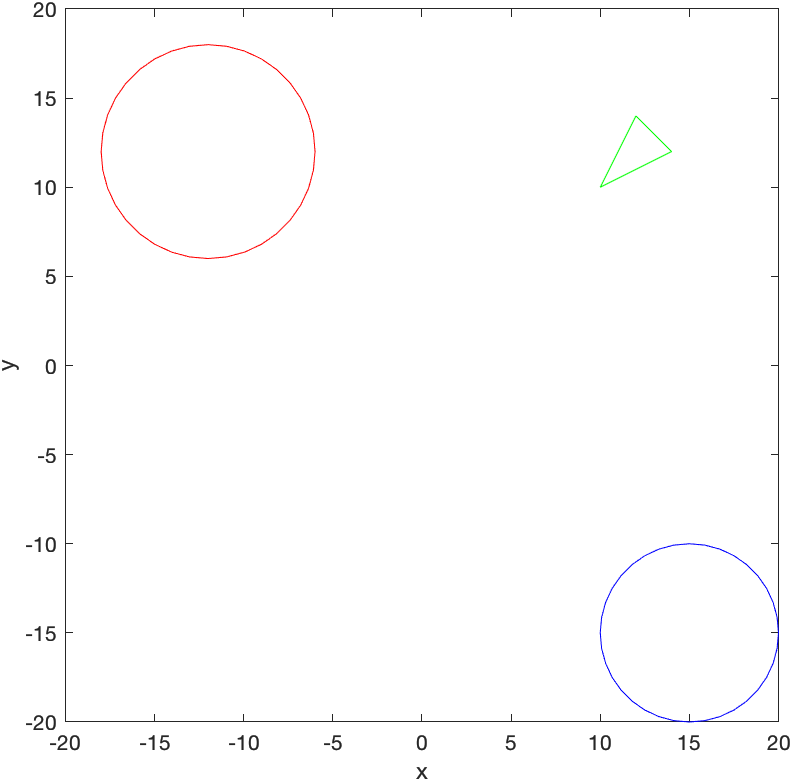

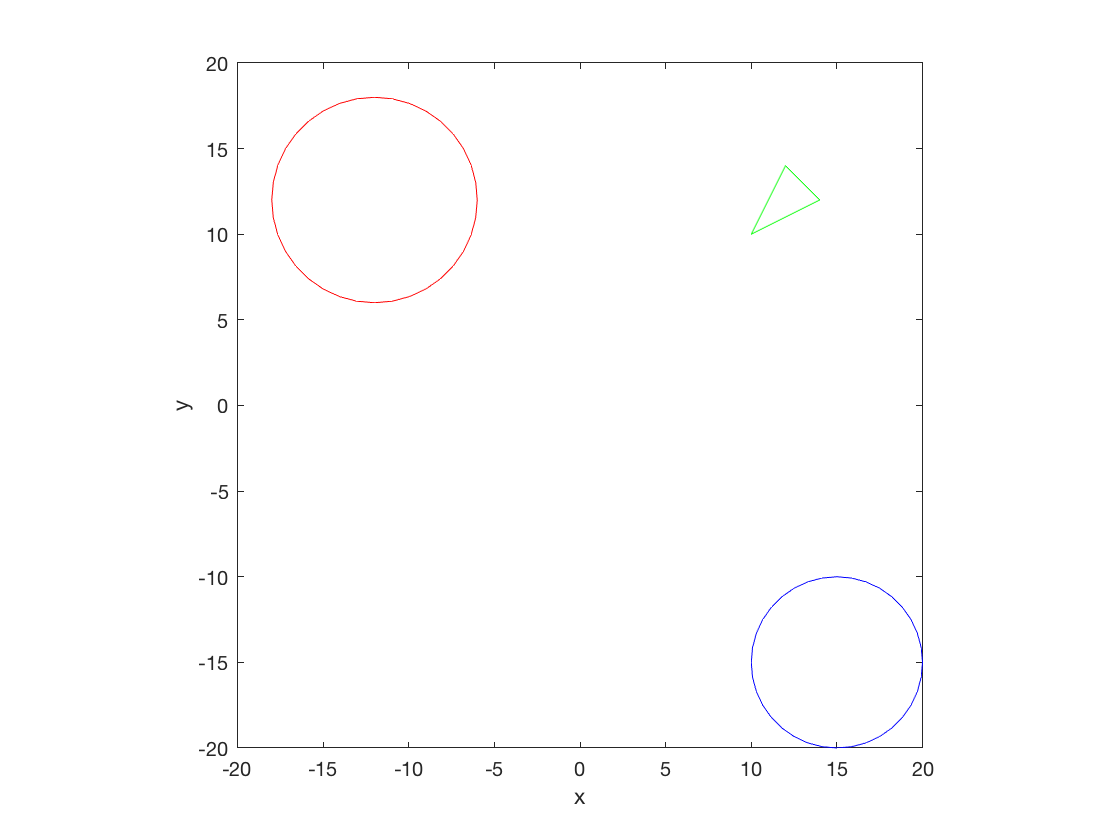

% Plot red circle
x = zeros(37, 1);
y = zeros(37, 1);

for i = 1 : 37
    x(i) = 6 * cos(pi / 18 * i) - 12;
    y(i) = 6 * sin(pi / 18 * i) + 12;
end

plot(x, y, 'r')
hold on

% Plot blue circle
x = zeros(37, 1);
y = zeros(37, 1);

for i = 1 : 37
    x(i) = 5 * cos(pi / 18 * i) + 15;
    y(i) = 5 * sin(pi / 18 * i) - 15;
end

plot(x, y, 'b')

% Plot green triangle
x = [ 10, 14, 12, 10 ];
y = [ 10, 12, 14, 10 ];

plot(x, y, 'g')
hold off

axis([ -20, 20, -20, 20 ])
axis square
xlabel('x')
ylabel('y')

(b) Write a program that plots a set of 5 magenta squares, each of side length 2 units on a set of axes where $x\in [0, 40]$. The bottom left corner of the first square should be positioned at the origin. The other 4 squares should be positioned **above and to the right** of the first square with a **horizontal gap of 1 unit** and a **vertical gap of 0 units** . You **must use a loop** to draw the 5 squares rather than set of repeated statements. 

Your plot should look like the following:

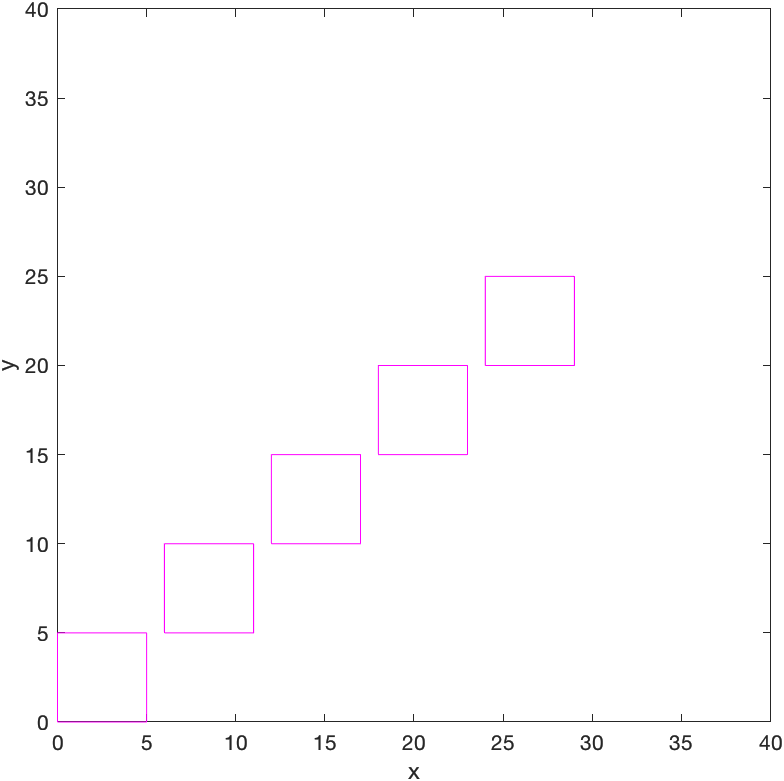

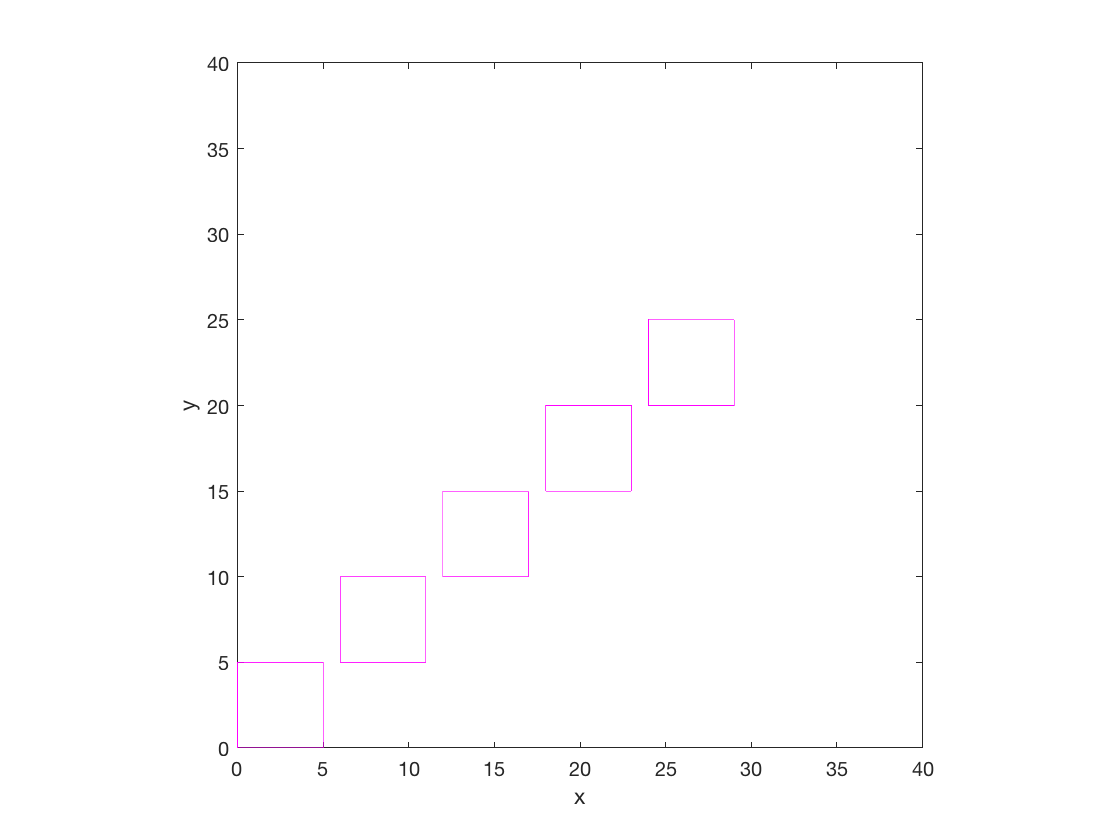

% Co-ordinates of the first square
x = [ 0, 5, 5, 0, 0 ];
y = [ 0, 0, 5, 5, 0 ];

% Plot squares
for i = 1 : 5
    plot(x + (i - 1) * 6, y + (i - 1) * 5, 'm')
    hold on
end
hold off

axis([ 0, 40, 0, 40])
axis square
xlabel('x')
ylabel('y')

(c) Write a program to draw set of 5 circles, each with centre at $(25, 25)$ on a set of axes where $x, y \in [0, 50]$ . The circles should decrease in radius from 20 to 5 in steps of -5. The circles should appear in alternate colours, red and blue, with the largest circle drawn in red. Again you **must use a loop** to draw the 5 circles and use an if statement to draw the circles in the correct colour.

Your plot should look like the following:

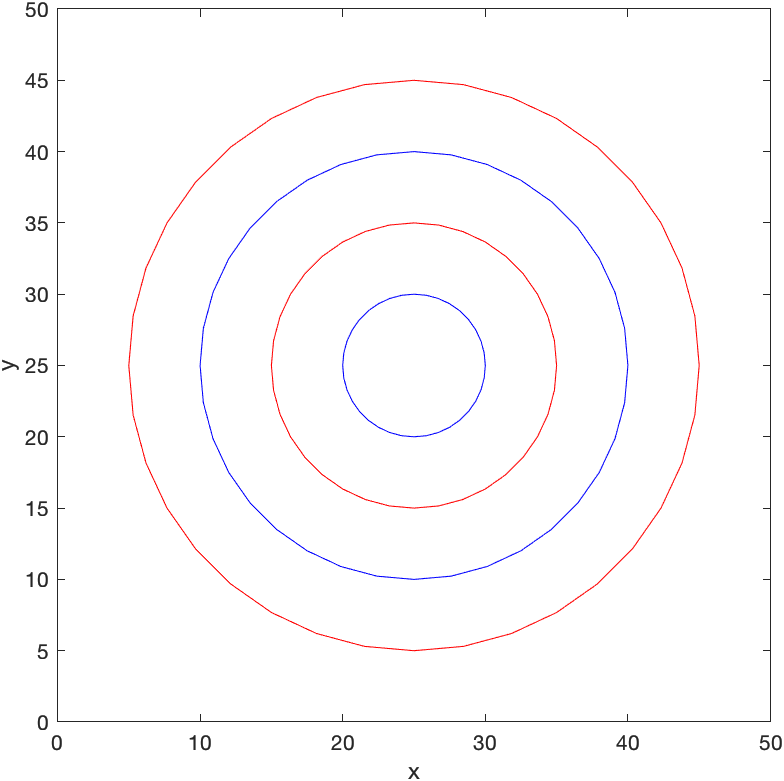

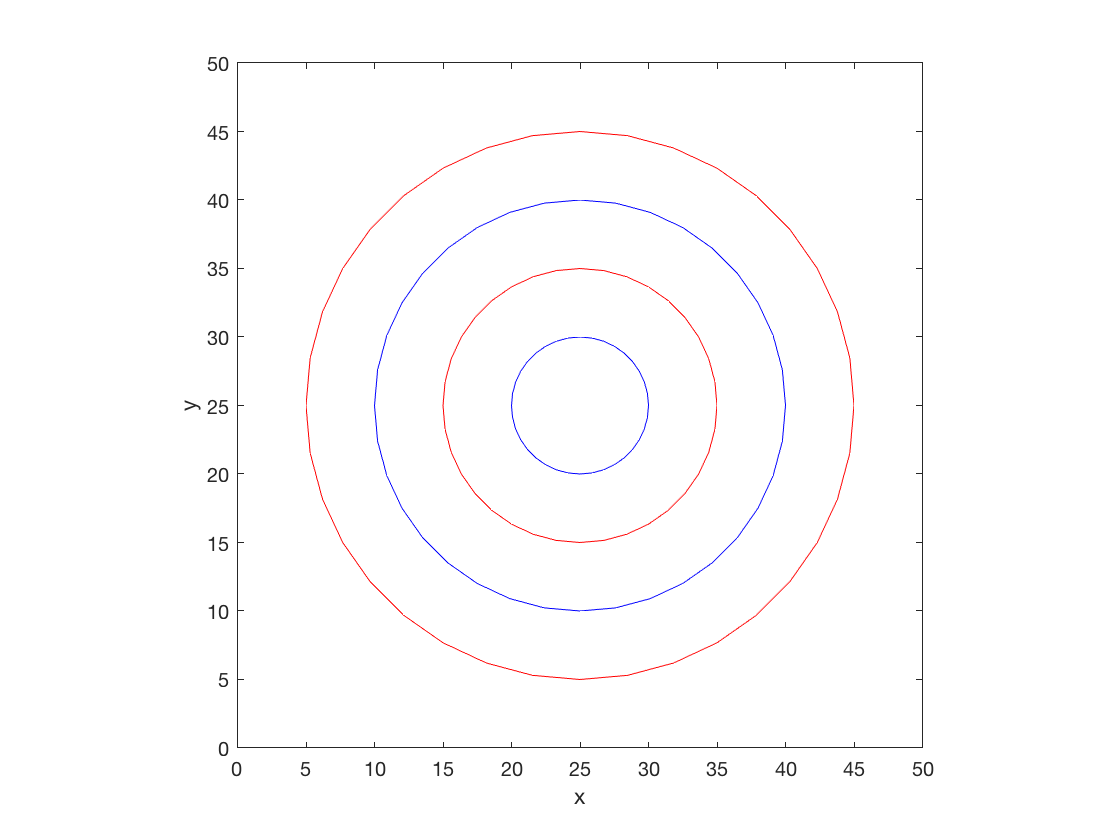

% Loop through the circles
colour = 'r'; % colour of outside circle
for radius = 20 : -5 : 5
    
    % Calculate circle co-ordinates
    x = zeros(37, 1);
    y = zeros(37, 1);
    for i = 1 : 37
        x(i) = radius * cos(pi / 18 * i) + 25;
        y(i) = radius * sin(pi / 18 * i) + 25;
    end
    
    % Plot circle
    plot(x, y, colour);
    hold on
    
    % Determine colour of next circle
    if colour == 'r'
        colour = 'b';
    else
        colour = 'r';
    end
end
hold off

axis([ 0, 50, 0, 50 ])
axis square 
xlabel('x')
ylabel('y')

### Question 6

(a) The following expression defines a sequence of $x$ values


$$x_{n+1} = \frac{1}{2} \left( x_{n} + \frac{5}{x_{n}} \right).$$


For example, given a starting value of $x_0=1$


$$    x_0 = 1, \\
    x_1 = 3, \\
    x_2 = 2.3333, \\
    x_3 = 2.2381, \\
    \vdots$$


Write a program to calculate the values in this sequence using a starting value of $x_0=5$ upto $x_5$ and stores them in a one-dimensional array. Use a print command to output the array.

X = zeros(6, 1);
X(1) = 5;

for n = 1 : 5
    X(n + 1) = 1 / 2 * (X(n) + 5 / X(n));
end
X

X =     5.0000
    3.0000
    2.3333
    2.2381
    2.2361
    2.2361


(b) Using a `for`** loop**, produce a table of this sequence with a column for the the values of $n$ and another column for the values of $x_n$ correct to 7 decimal places, i.e.,

% Use for loop with single iteration to keep printed lines together (not
% really necessary but makes it look nicer)
for i = 1 : 1
    fprintf(' n     xn\n--------------')
    for n = 1 : 6
        fprintf(' %1i %10.7f\n', n, X(n))
    end
end

 n     xn
--------------

 1  5.0000000
 2  3.0000000
 3  2.3333333
 4  2.2380952
 5  2.2360689
 6  2.2360680


    (c) Define a function called `mysequence2` that calculates the following sequence given inputs for the starting value $x_0$, the value of $b$ and the maximum value of $n$, and stores the values in a one-dimensional array.


$$x_{n+1} = \frac{1}{2} \left( x_n + \frac{b}{x_n} \right).$$


Using your function, produce **four** tables of this sequence up to $x_4$ for $x_0=b$ and the value of $b$ changing from 7 to 13 in steps of 2. You **must use a **`for`** loop** to loop through the values of $b$.

% Loop through the values of b
for b = 7 : 2 : 13
    
    % Calculate sequence array
    X = mysequence2(b, b, 4);
  
    % Output table
    % Use for loop with single iteration to keep printed lines together (not
    % % really necessary but makes it look nicer)
    for i = 1 : 1
        fprintf(' \n n      xn\n--------------')
        for n = 1 : length(X)
            fprintf(' %1i  %10.7f\n', n - 1, X(n))
        end
    end
end

 
 n      xn
--------------

 0   7.0000000
 1   4.0000000
 2   2.8750000
 3   2.6548913
 4   2.6457670


 
 n      xn
--------------

 0   9.0000000
 1   5.0000000
 2   3.4000000
 3   3.0235294
 4   3.0000916


 
 n      xn
--------------

 0  11.0000000
 1   6.0000000
 2   3.9166667
 3   3.3625887
 4   3.3169389


 
 n      xn
--------------

 0  13.0000000
 1   7.0000000
 2   4.4285714
 3   3.6820276
 4   3.6063455


### Question 7

(a) Write a program that defines a two-dimensional array which is equivalent to the following matrix. Using a pair of nested `for` loops calculate and output the number of 1s in the matrix. 


$$X = \pmatrix{ 1 & 0 & 1 \cr 2 & -3 & 2 \cr 1 & 0 & -2 }$$


Your output should appear in the following form

X = [ 1, 0, 1 ; 2, -3, 2 ; 1, 0, -2 ];
count = 0;

for i = 1 : 3
    for j = 1 : 3
        if X(i, j) == 1
            count = count + 1;
        end
    end
end

fprintf('number of 1s = %1i', count)

number of 1s = 3

(b) Define a function called `distance` that given inputs of the co-ordinates of two points in $\mathbb{R}^2$ as two-element arrays of the form $(x_1, y_1)$ and $(x_2, y_2)$, calculates and returns the distance between the two points using the formula


$$\text{distance} = \sqrt{(x_1 - x_2)^2 + (y_1 - y_2)^2}$$


Use your function to calculate the distance between the points $(1.3, 5.7)$ and $(7.9, -0.8)$.

% Define co-ordinate arrays
point1 = [ 1.3, 5.7 ];
point2 = [ 7.9, -0.8 ];

% Calculate distance between the two points
dist = distance(point1, point2)

dist = 9.2634

(c) The area of a triangle defined in $\mathbb{R}^2$ with vertices $(x_1, y_1)$, $(x_2, y_2)$ and $(x_3, y_3)$ can be calculated using the formula


$$\text{area} = \frac{1}{2} \det \pmatrix{ x_1 & y_1 & 1 \cr x_2 & y_2 & 1 \cr x_3 & y_3 & 1 }.$$


Define a function called `triangle_area` that given inputs to the vertex co-ordinates calculates the area of the triangle. You may use the `det` command from MATLAB or the NumPy library in Python. Use your function to calculate the area of the triangle with vertices $(0, 1)$, $(5, 2)$ and $(2, 7)$.

% Define vertex co-ordinate arrays
vert1 = [ 0, 1 ];
vert2 = [ 5, 2 ];
vert3 = [ 2, 7 ];

% Calculate the area of the triangle
area = triangle_area(vert1, vert2, vert3)

area = 14

### Question 8

(a) The following expression gives the probability of correctly choosing 6 lottery balls from a possible 59,


$$\frac{1}{59} \times \frac{2}{58} \times \frac{3}{57} \times \frac{4}{56} \times \frac{5}{55} \times \frac{6}{54}.$$


Write a program which calculates and outputs this value to **10 decimal places** with suitable preceding text on the same line. The program **must use a **`for`** loop** to perform the calculation.

x = 1;

for i = 1 : 6
    x = x * i / (60 - i);
end

fprintf('The probability of correctly choosing 6 lottery balls from a possible 59 is %1.10f', x)

The probability of correctly choosing 6 lottery balls from a possible 59 is 0.0000000222

(b) The series below calculates the value of $\cos(x)$ for a given value of $x$


$$\cos(x) = \sum_{n=0}^\infty \frac{(-1)^nx^{2n}}{(2n)!} = 1 - \frac{x^2}{2!} + \frac{x^4}{4!} - \frac{x^6}{6!} + \cdots$$


Write a program to calculate the value of this series given the $x$ value and number of terms. You may use the `factorial` command from MATLAB or the `math` library in Python.  Use your program to calculate the value of $\cos(0.5)$ using 4 terms and print the result correct to **5 decimal places**.

x = 0.5;
nterms = 4;
cosx = 0;

for n = 0 : 3
    cosx = cosx + (-1) ^ n * x ^ (2 * n) / factorial(2 * n);
end

fprintf('cos(%1.2f) = %1.5f', x, cosx)

cos(0.50) = 0.87758

(c) Define a function called `mycos` that uses the series from part (b) and a `while`** loop** to calculate the value of $\cos(x)$ ceasing iterations when the **absolute** difference between successive approximations is less than $10^{-6}$. Use your function to calculate $\cos(1)$ and output the result correct to **8 decimal places**.

fprintf('cos(%1.2f) = %1.8f', 1, mycos(1))

cos(1.00) = 0.54030230

## Functions

Question 1 (b)

function invA = inv_2x2(A)

% Calculates the inverse of a 2x2 matrix

% Check for singularity
detA = A(1, 1) * A(2, 2) - A(1, 2) * A(2, 1);
if detA == 0
    fprintf("Warning, matrix is singular")
    return
end

% Calculate inverse
invA = [ A(2, 2), -A(1, 2) ; -A(2, 1), A(1, 1) ] / detA;

end


Question 2 (c)

function detA = mydet(A)

% Calculates the determinant of a 2x2 matrix

[rows, cols] = size(A);
if rows ~= 2 || cols ~= 2
    fprintf('Error, input must be a 2 x 2 matrix')
    return
end

detA = A(1, 1) * A(2, 2) - A(1, 2) * A(2, 1);

end

Question 4 (c)

function X = mysequence(x0, nterms)

X = zeros(nterms, 1);
X(1) = x0;

for n = 2 : nterms
    X(n) = (X(n - 1) ^ 2 - 1) / (2 * X(n - 1) - 3);
end

end

Question 6 (c)

function X = mysequence2(x0, b, nmax)

X = zeros(nmax + 1);
X(1) = x0;

for n  = 1 : nmax
    X(n + 1) = 1 / 2 * (X(n) + b / X(n));
end

end

Question 7 (b)

function dist = distance(p1, p2)

% Calculates the distance between two points in R2
dist = sqrt((p1(1) - p2(1)) ^ 2 + (p1(2) - p2(2)) ^ 2);

end

Question 7 (c)

function area = triangle_area(v1, v2, v3)

% Calculates the area of a triangle in R2
X = [ v1(1), v1(2), 1 ; v2(1), v2(2), 1 ; v3(1), v3(2), 1 ];
area = 1 / 2 * det(X);

end

Question 8 (c)

function cosx = mycos(x)

% Calculate cos(x)

cosx = 0;
n = 0;
term = 1;

while abs(term) > 1e-6
    term = (-1) ^ n * x ^ (2 * n) / factorial(2 * n);
    cosx = cosx + term;
    n = n + 1;
end

end